# Microgrid Design and Simulation: **Solar Pumping**

GROUP NAMES: Thomas Hudson, Zhen-Yu, Yen-Chun

Project Type: **Solar Pumping**

December 10, 2024

## Solar Pumping Microgrid - Description and Overview

This microgrid project includes non-grid supplied power systems for domestic water supply and electrical lighting serving a small community in Uganda.

In Uganda clean, potable water is often attained from vertical boreholes where aquifers are available. Hand pump kiosks allow for manual extraction of water but this is not effective for larger communities where community members face long wait times (figure 1.1).

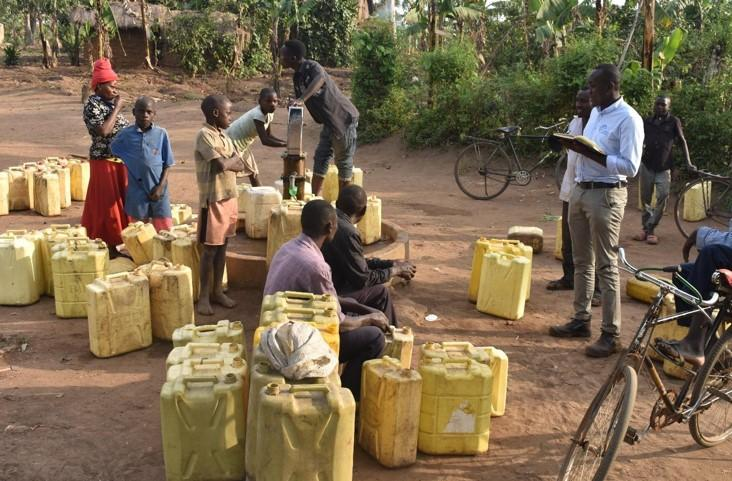

*Figure 1.1: People waiting to pump water.*

This microgrid project develops electric power to pump domestic water from a borehole to a water storage tank. The system is designed to serve a community of 1800 persons. Figure 1.2 shows a general solar pumping diagram.

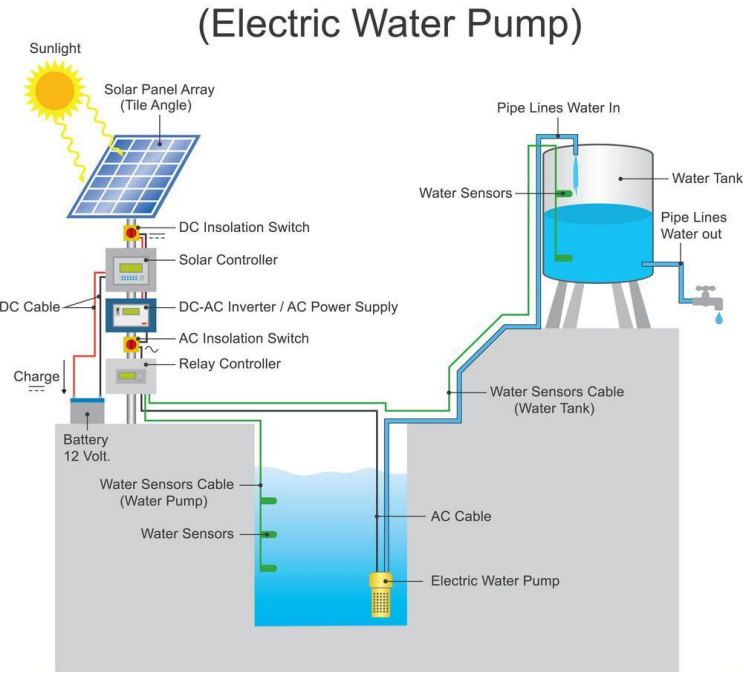

*Figure 1.2: General components for solar water pumping.*

Microgrid design permaeters for our community are based on an Engineering Without Borders 2020 implementation report by the Penn State University chapter of Engineers Without Borders. The chapter worked with the community of Namutamba for several years to understand design requirements such as daily water volume requirements and water storage. 

Water storage is required for buffering against cloudy days when the microgrid power source for water pumping is not available.

This microgrid project includes electrical power and electrical storage requirements to serve a small school house. Electrical stroage is required for inclement weather where daily power resources fall below average. 

Microgrid projects (non-grid tied) with similar designs are implemented by Engineers Without Borders chapters in a number of African countries. Figure 1.3 shows solar projects in Uganda and Kenya where each colored circle indicates a solar installation. Reasons for solar adoption are solar can be more reliable than grid power, less expensive than grid power, and solar can be erected where needed. 

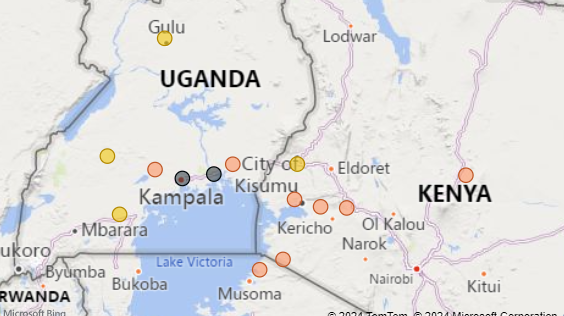

*Figure 1.3: EWB Solar Installation Projects.*

Satellite images (figure 1.4) show large open areas that favor solar installation sites. The community is low density with few structurs and land use includes agriculture. The Pen State University chapter has completed reports describing the demographic and socioeconomic profiles for the community.

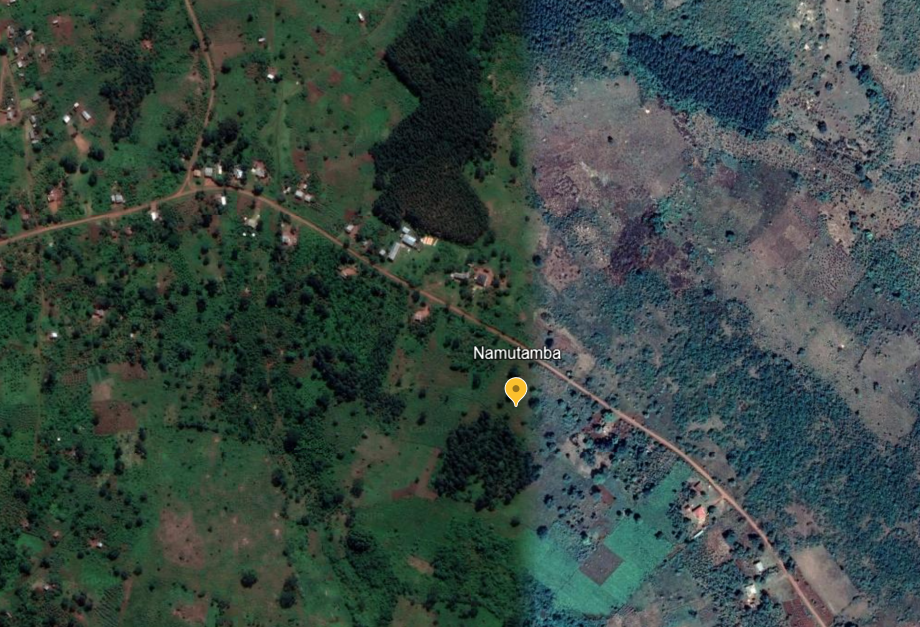

*Figure 1.4: Satelite image of Uganda community.*

The community is located at:  

- latitude:  0.5345

- longitude: 32.0877

## Load Calculations

This project is designed to power both a water pump and electrical loads for a small school house.

### - Electrical Lighting

The school house floor plan is shown 2.1 with a floor area of 77 sqm (UNICEF architectural designs for schools in Rwanda).

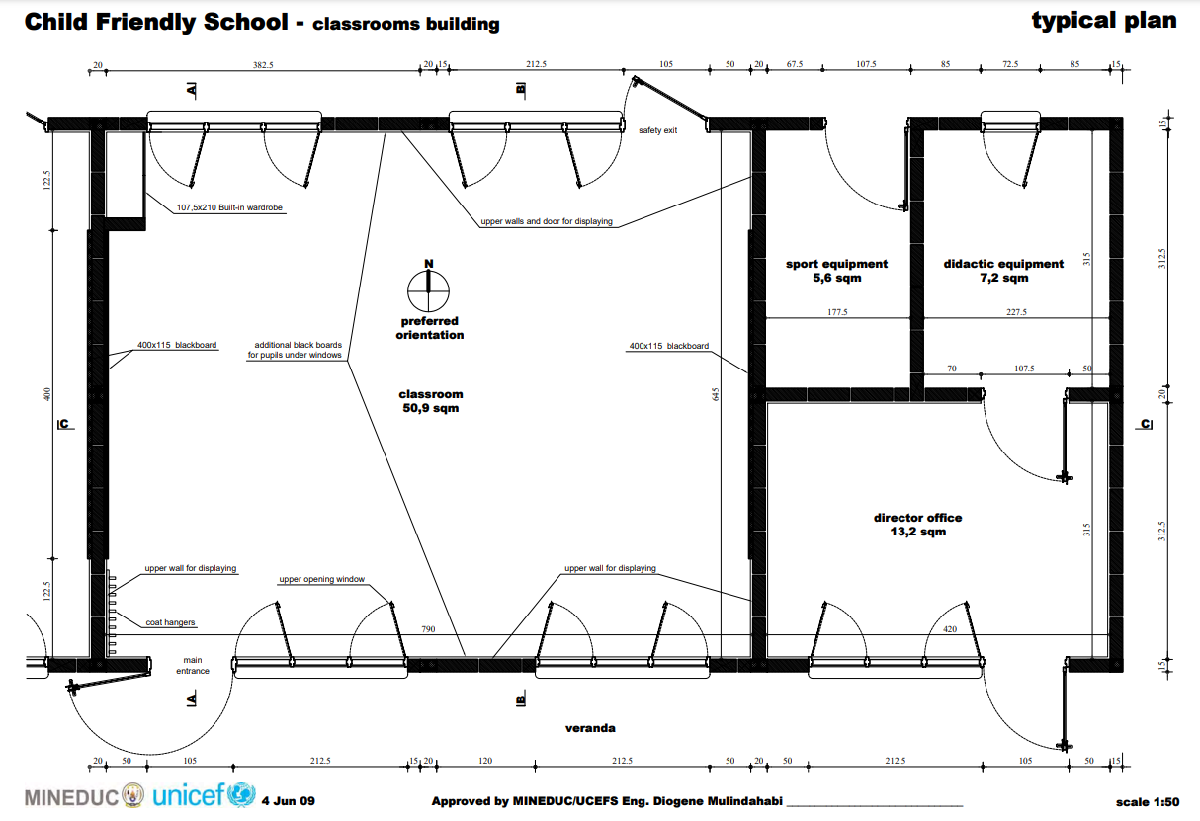

*Figure 2.1: School house drawing.*

The project scope for the school house includes power for lighting and a few small plug loads for computers and a printer. Electrical lighting power continues to fall with the adoption of LEDs. Several US states have adopted the 2021 International Energy Conservation Code (IECC) standards, including its lighting power density (LPD). The 2021 IECC standards (LPD) is 0.71 watts per square foot(w/sqft) or 7.64 w/sqm. These standards are appropriate for this project as LED lighting is available in Uganda.

Plug Load estimates include 4 laptops and a small printer. Laptops are estimated to run 30 watts per device and operational 24 hrs/day. A small printer is estimated to draw 50watts and is operational 24 hrs/day.

**・ School Electrical Lighting and Power**

Electrical_Power_Use = 7.64 * 77; % 77sqm = 588 watts
Laptops = 4 * 30; % watts/each = 120 watts
Printer = 50; % watts
Total_Plug_Power = 120 + 50; % total power plug loads: 170 watts
Total_Power_School = Electrical_Power_Use + Total_Plug_Power; % total power all loads 758 watts

fprintf('Electrical_Power_Use: %0.1f watts \n',Electrical_Power_Use);

Electrical_Power_Use: 588.3 watts 


fprintf('Total_Plug_Power: %0.1f watts \n',Total_Plug_Power);

Total_Plug_Power: 170.0 watts 


fprintf('Total_Power_School: %0.1f watts \n',Total_Power_School);

Total_Power_School: 758.3 watts 


**・ Daily Use Assumptions**

School Operational Hours: 6 days/week 8am - 5pm with 2 hours evening classes 3 times per week. 

Total Operational Hours per week = 6 days * 9 hrs + 3 days * 2 hrs = 60 hrs

**・ Energy Use School per year**

Energy_Lighting = 60 * 52 * Electrical_Power_Use/1000; % = 1,834 kWh
Energy_Plug_Loads = 24 * 365 * Total_Plug_Power/1000; % 1,489 kWh
Total_Energy_School = Energy_Lighting + Energy_Plug_Loads; %kWh

fprintf('Energy_Lighting: %3.f kWh \n',Energy_Lighting);

Energy_Lighting: 1835 kWh 


fprintf('Energy_Plug_Loads: %3.f kWh \n',Energy_Plug_Loads);

Energy_Plug_Loads: 1489 kWh 


fprintf('Total_Energy_School: %3.f kWh \n',Total_Energy_School);

Total_Energy_School: 3325 kWh 


This estimate includes no safety margins for estimated electrical lighting power or lighting schedules at this time.

### - Domestic Water Pumping 

Uganda has a national water standard of 20 liters per day per person. Our community of 1,800 persons requires 36,000 liters per day. The average water flow is calculated to be 1,500 liters/hr to deliver the reqiured volume in a 24 hour period. This initial opperational assumption is that electrical power is available 24 hours a day.

The total static head pressure required includes the depth of the well and head pressure to move the water from the well to a reservoir. The total dynamic head pressure is estimated at 154 to 170 meters.

Figure 2.2 is a data of available pumps to meet varius pressures and flows. All these pumps can deliver 1,500 liters/hr (x-axis) and the red lines indicate the requred band of 154 to 170 meters for this project. SP 2A-48 can deliver the flow and pressure required. Another pump not shown on this data sheet is SP 2A-40 that lies junst under SP 2A-48 and can deliver the flow at that specified pressure. This pump has a 2.2 kw (3hp) motor. The datasheet shows 0.04 kW power per stage and the SP 2A-40 has '40 stages.' The pump power is then given as 0.04 kw x 40 stages for 1.6 kW. Pump selection is well within the estimated requiremetns but no pumping power safetly margins are included in these calculations at this time.

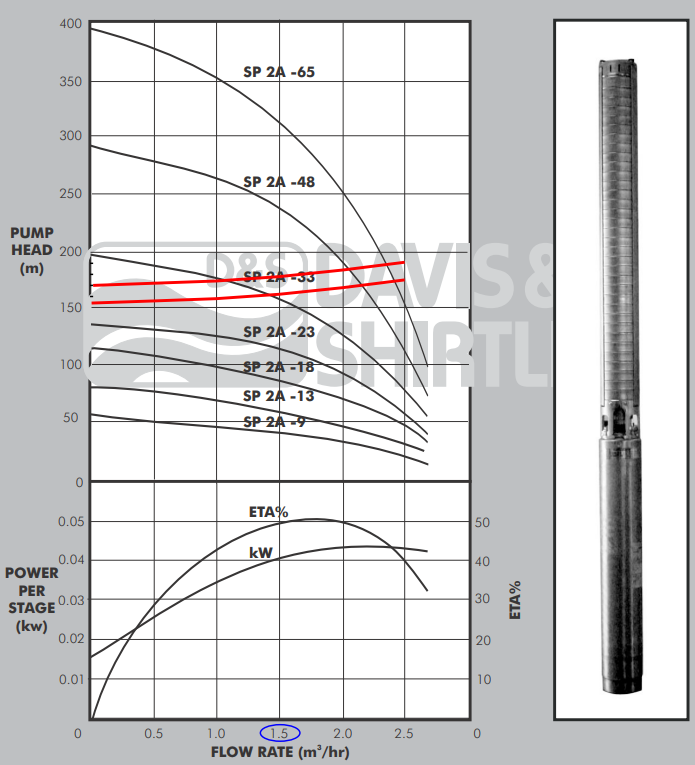

*Figure 2.2: Grundfos pump data sheet. The red lines indicate the operational band.*

Pump_power = 0.040 * 40; % 1.6 kW
fprintf('Pump_power: %0.1f kW\n',Pump_power)

Pump_power: 1.6 kW


**Energy pumping power**

As with the electrical lighting, this assessment assumes power is available 24 hours a day for pumping. The pumping energy estimate is therefore given as:

Annual_Pumping_energy = Pump_power * 365 * 24; % 14,016 kWh
fprintf('Annual_Pumping_energy: %3.0f kWh \n',Annual_Pumping_energy);

Annual_Pumping_energy: 14016 kWh 


Under this assessment the reservoir will be sized to hold sufficient water for daily use fluctuations but the pump will continuously fill the reservoir and the peak power will match the pump power: 1.6kW.

### - MicroGrid Peak Power

The current estimated loads assume power is always available. 

The total electrical lighting loads and pumping loads are given as: 

Peak_Power = Total_Power_School/1000 + Pump_power; % 2.36 kW
fprintf('Peak_Power: %2.2f kW \n',Peak_Power);

Peak_Power: 2.36 kW 


### - MicroGrid Annual Energy Use

The annual energy usage includes electrical lighting and pumping energy and is given as:

Annual_Energy_Use = Total_Energy_School + Annual_Pumping_energy; %3,323 kWh + 14,016 kWh = 17,339 kWh
fprintf('Annual_Energy_Use: %3.0f kWh \n',Annual_Energy_Use);

Annual_Energy_Use: 17341 kWh 


### - MicroGrid Load Factor

This inital design reflects the 'grid like' access to electrial power; that is, electrical power is assumed to be available when needed from microgrid resources. The 1.6 kW pumping power will likely be constant as it has been sized for 24 hour operation. If the pump does turn off it will occur when little water is being used (at night) and once the reservoir has been filled. Electrical lighting power usage is shown here to operate during a Monday through Saturday and 8am - 5pm schedule and contributes to the lower load factor.

The load factor is given as Total Annual Energy Use / (Peak Demand * 365 days)

Load_factor = Annual_Energy_Use/(Peak_Power * 24 * 365);
fprintf('Load Factor: %0.2f \n\n\n',Load_factor);

Load Factor: 0.84 




## Summary of Homer Output

To utilize Homer, we need to know several key factors for our design: daily average load, solar cost, wind turbine cost, battery cost, and deisel price in Uganda.

### **- Daily Average Load & Daily Peak Load**

We simply take the annual energy use (Annual_Energy_Use) divied by 365, and hourly peak load (Peak_Power) times 24, then we can get:

fprintf('Average Load: %0.2f kWh/day, Peak Load: %0.2f kWh/day\n', Annual_Energy_Use/365,Peak_Power*24);

Average Load: 47.51 kWh/day, Peak Load: 56.60 kWh/day


Thus, we set the Average Load to 47.51 kWh/day. The variability is set to 4% hourly and 2% daily to match our load factor of 0.84 as closely as possible.

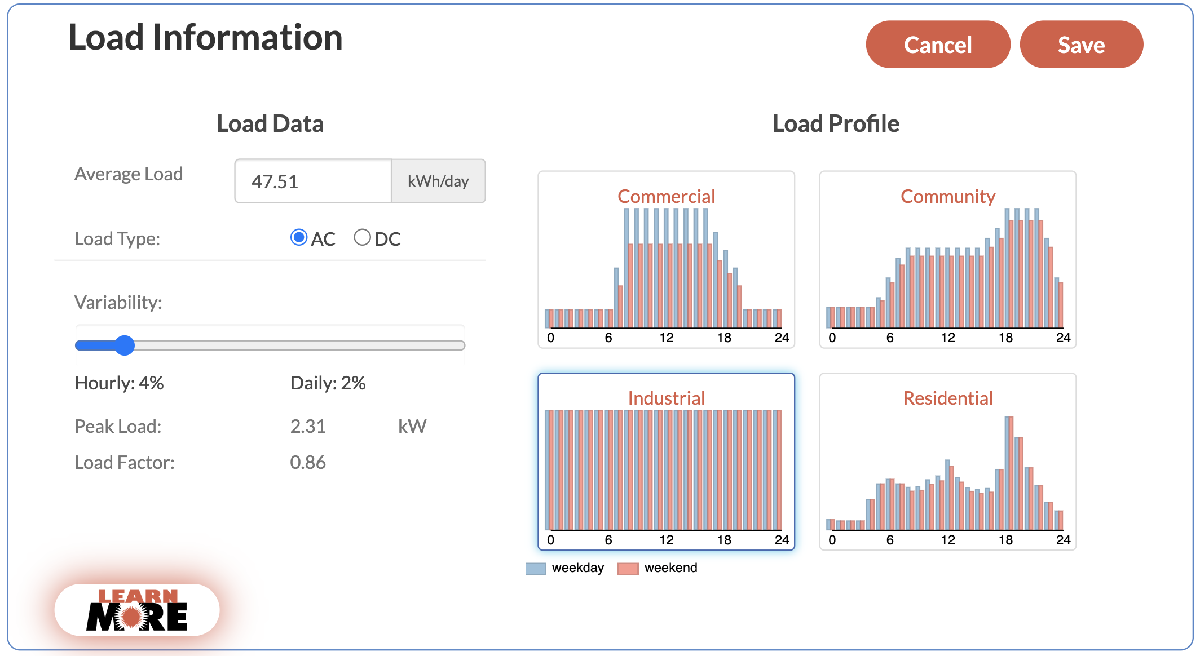

*Figure 3.1 The Load Information setting for Homer Calculation.*

### **- Solar Cost**

Since Uganda is spacious and the funding is relatively lower, we selected utility ground mount solar system for our design. According to the data from the National Renewable Energy Laboratory [4], the latest (2023) utility ground mount solar cost is 1.2 $/W, as shown in Figure 3.2.

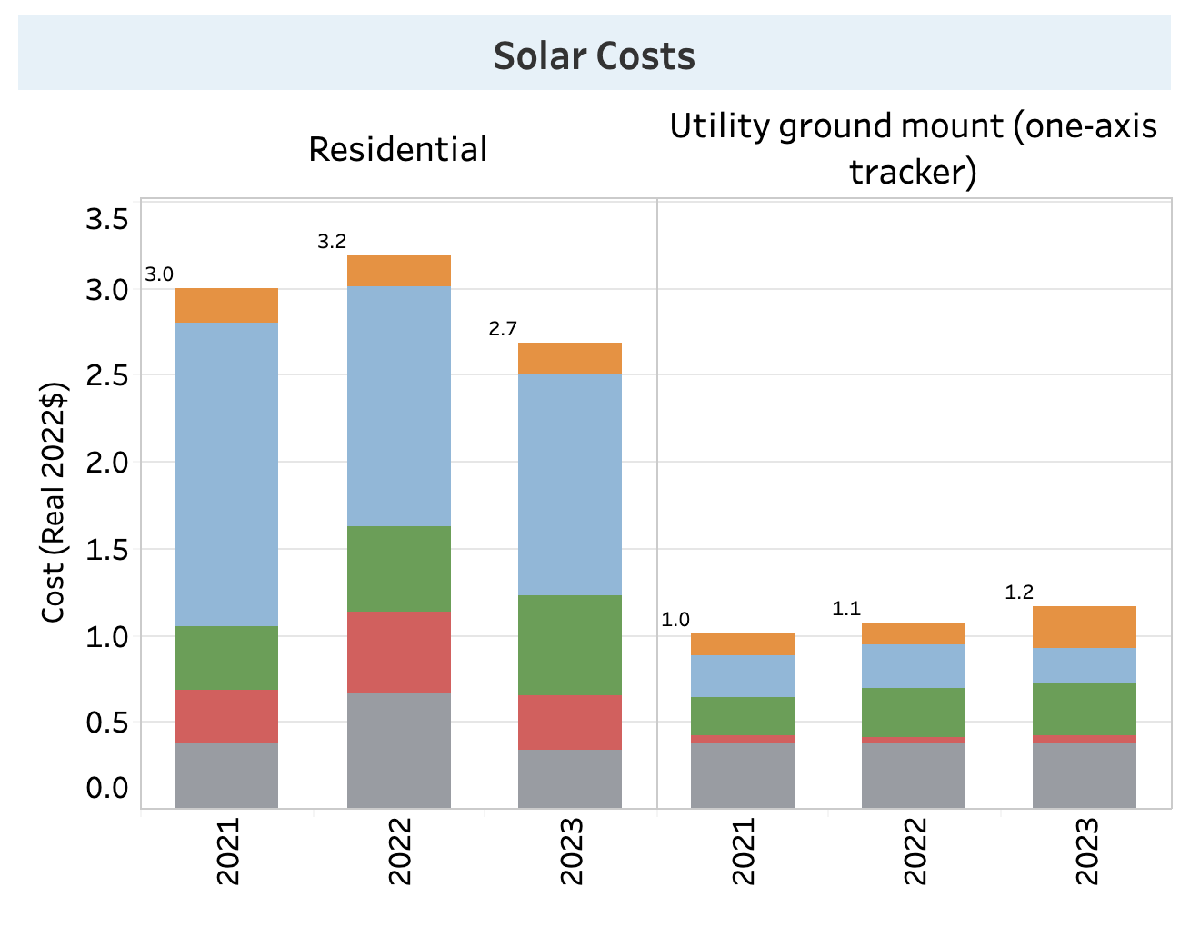

*Figure 3.2 Solar Costs in 2023 from NREL (National Renewable Energy Laboratory).*

### **- Wind Turbine Cost**

In our micro-grid design, we decided not to include wind power due to several important limitations [5]. First, Uganda lacks adequate and high quality wind data collected at the heights needed for energy assessments. Most wind data was gathered at lower altitudes for weather forecasting, making it less reliable for planning wind turbine installations. In addition, the high initial costs of installing wind energy infrastructure pose a huge challenge, especially in areas with limited funding for renewable energy projects. Lastly, Uganda's current energy policies offer very little support or specific incentives for wind power. This reduces the likelihood of investment in this area. Overall, these factors make wind power less practical for our project. Unsurprisingly, the result of the Homer calculation also excludes wind power, as shown in Figure. 3.4.

### **- Battery Cost**

- Use generic 1 kWh lithium ion batteries.

- Use $140 per battery.

### **- Diesel Price**

According to the Global Petrol Prices website [6], the latest deisel price in Uganda is 1.278 USD/Liter (11-Nov-2024).

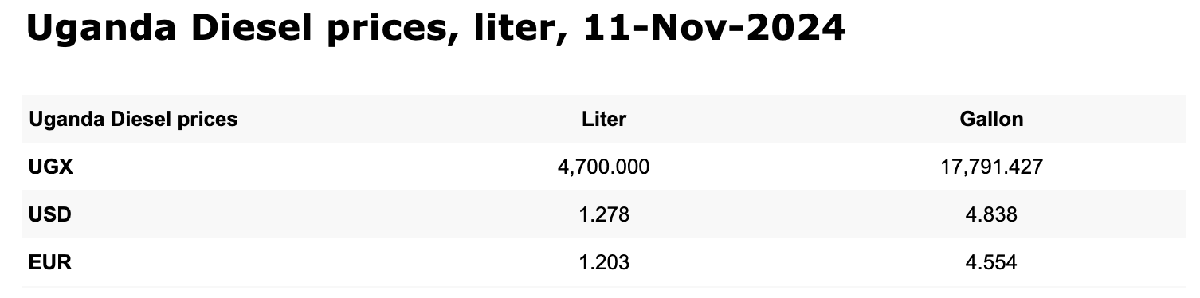

*Figure 3.3 Uganda Diesel prices from Global Petrol Prices website.*

### **- Homer Output**

All things considered, the simulation output from Homer is shown in Figure 3.4. We chose the micro-grid configuration with the lowest NPC, $94,924, since it is the most cost effective. This system includes a diesel generator with a capacity of 3 kW, complemented by solar PV with a capacity of 9.7 kW, and supported by 4 Li-lon batteries with a capacity of 1 kWh. This configuration requires an initial capital investment of $14,231, with an annual operating cost of $5,123, achieving a COE of $0.35 per kWh. The diesel generator consumes 3,155 liters of fuel per year to ensure energy availability when solar output is insufficient. For more detailed information, please refer to the system report ([link](https://drive.google.com/file/d/1boekQl9hlhDZMRc6JIFEr2sqHfh6gaBv/view?usp=sharing)). 

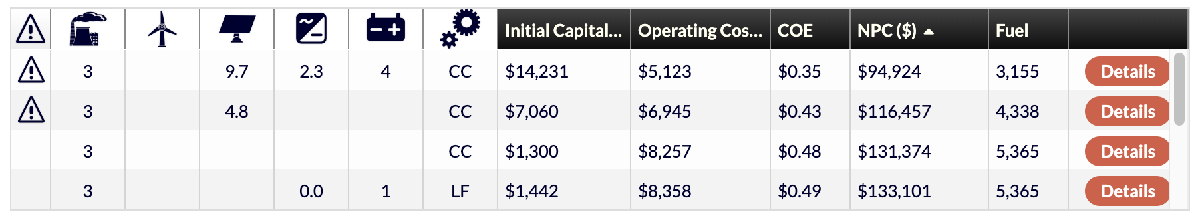

*Figure 3.4 The Homer ouput.*

## Translating Homer's Outputs to MATLAB/Simulink

The communities mean power and peak power are used to inform the load profile for the simulation and are given as follows:

meanLoad = 1.98e3; % Average load in Watts
peakLoadPower = 2.36e3; % in Watts

Although are simulation currently does not include wind, the average wind speed and number of turbines is as follows:

meanWindSpeed = 3.37; % Annual Average (m/s), currently not used
wt.N_turbines = 0; % Not used

Homer estimated 4 kWh of battery supply or 1.44e7 Joules. As a starting point we have set the rated power electronis to our peak power (2.36kW). This may have to be adjusted upwards by ~10% if we need full power and have to account for power electronics efficiencies. 

es.E_rated = 4 * 1000 * 60 * 60;  % 1.44e7 Enegy Storage rated energy in Joules

    es.E_rated = 1.44e7; % Energy storage rated energy in Joules    

es.P_pe_rated = 2.36e3; % Energy storage rated power in Watts

Homer sized the PV array for a rated capacity of 10kW.    

pv.P_rated = 10e3; % Solar PV rated power in Watts

The system's rated deisel generator capacity of 3kW translates to hydroturbine capacity as follows:    

ht.P_rated = 3.0e3;  %  hydroturbine rated power in Watts

The microgrid base power is set to our peak load power. This will define our normalization and per unit scaling.     

mg.P_base = 2.36e3; % Microgrid base power in Watts

The converter rated capacity translates to the power eletronics of the batteries capacity as follows: 

es.P_pe_rated = 2.3e3; % Converter rated power in Watts

## Simulation Results

% Simulate your system and plot the following:
% 
% # p_ld, p_wt, p_pv, p_es, p_ht
% # p_es on left axis and SOC on right axis
% # delta_wpu
%
% Comment on if the design is stable.
%
% Create a contingency condition, like the sudden loss of a microgrid
% component, or the passing of clouds, and test your system.
%
% Comment on the result.
%
% Make three additional comments on anything of interest in the performance
% of your microgrid.

### - Normal Condition

First, we go with a sunny day (illuminationcurrenttimeseries.mat) for our sloar generation.

microgrid_y24f_step10_init


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

With the original settings from the Homer output, the microgrid becomes unstable following the sunrise and experiences a critical failure around 9:00 am. This instability arises because the battery's rated power is insufficient to accommodate the rapid increase in PV power generation. As a result, the system is unable to maintain the frequency within the specified constraints. This highlights the need for modifications to the battery capacity or control strategies to ensure stability under high PV output conditions.

es.P_pe_rated = pv.P_rated;

To address this issue, we simply adjusted the converter's power capacity to match the PV system's capacity of 9.7 kW to evaluate its effect on stability. As anticipated, this adjustment resolved the power bottleneck successfully. However, a new issue arose when the batteries became fully charged, reaching a SOC of 1.01. The excess energy generation caused the delta frequency to exceed the acceptable constraints, resulting in another system failure.

To address this issue, we increased the energy storage capacity of the batteries and investigated the minimum capacity needed to stabilize the system. Starting with an initial capacity of 10 kWh, we incrementally increased the capacity in steps of 10 kWh for each trial to determine the smallest value that would ensure system stability. Ultimately, we found that a capacity of approximately 60 kWh was sufficient to stabilize the system.

es.E_rated_kWh = 60;
es.E_rated_kWh*1000*3600;

Then, we rerun the simulation.

log = sim("microgrid_y24f_step10").logsout;

Found algebraic loop that contains: 
microgrid_y24f_step10/pv/Sum4
microgrid_y24f_step10/pv/Gain3
microgrid_y24f_step10/pv/Sum2
microgrid_y24f_step10/pv/Gain1
microgrid_y24f_step10/pv/Math Function
microgrid_y24f_step10/pv/Sum3
microgrid_y24f_step10/pv/Gain2
microgrid_y24f_step10

Plot the simulation results of our stable microgrid. (We did not go with wind turbine power, thus, there will be no p_wt in the plots.)

#### **1. Plot p_ld, p_pv, p_es, p_ht**

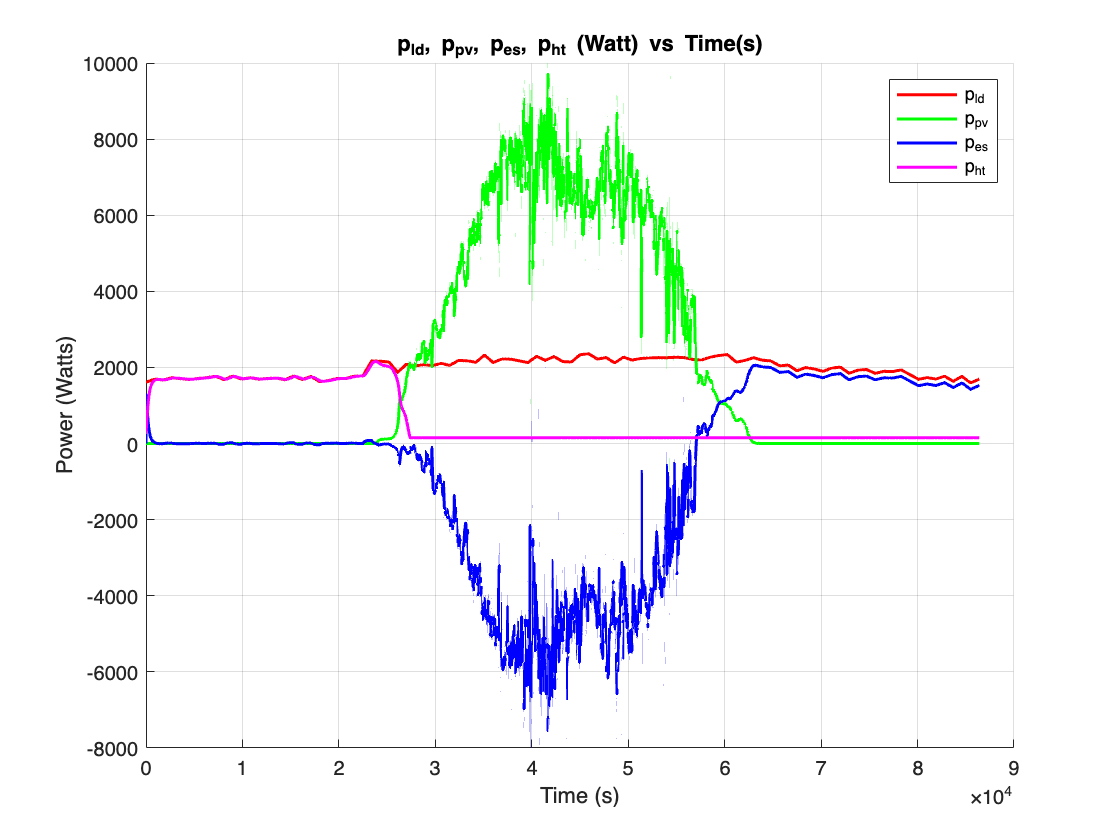

x = log.getElement("delta_wpu").Values.Time;

% Wind Turbine Power is not included in our design.
p_ld = log.getElement("p_ld").Values.Data;
p_pv = log.getElement("p_pv").Values.Data;
p_es = log.getElement("p_es").Values.Data;
p_ht = log.getElement("p_ht").Values.Data;

figure;
hold on;
plot(x, p_ld, "-r", 'LineWidth', 1.5);
plot(x, p_pv, "-g", 'LineWidth', 1.5);
plot(x, p_es, "-b", 'LineWidth', 1.5);
plot(x, p_ht, "-m", 'LineWidth', 1.5);
hold off;
xlabel('Time (s)');
ylabel('Power (Watts)');
legend({"p_{ld}","p_{pv}", "p_{es}", "p_{ht}"});
title('p_{ld}, p_{pv}, p_{es}, p_{ht} (Watt) vs Time(s)');
grid on;

#### **2. Plot p_es on left axis and SOC on right axis**

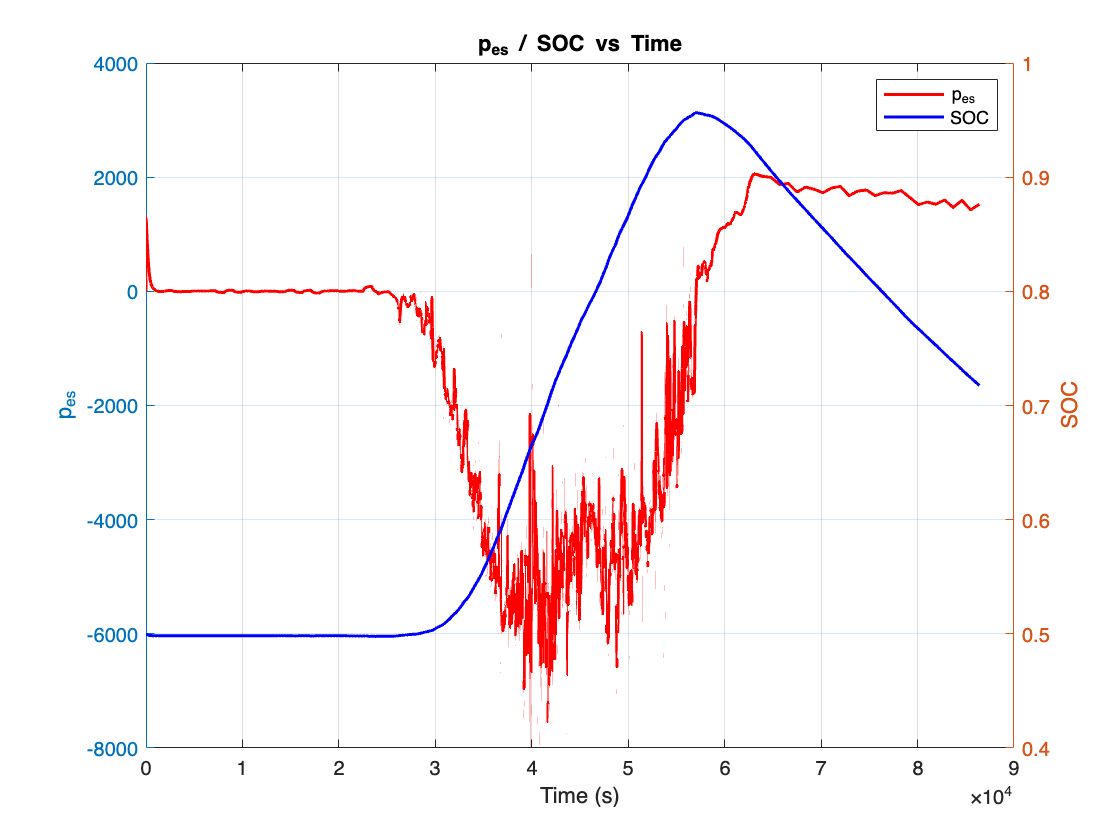

SOC = log.getElement("SOC").Values.Data;
figure
yyaxis left
plot(x,p_es,"-r", 'LineWidth', 1.5)
ylabel("p_{es}")
yyaxis right
plot(x,SOC,"-b", 'LineWidth', 1.5)
ylabel("SOC")
legend({"p_{es}","SOC"})
xlabel("Time (s)")
title("p_{es} / SOC vs Time")
grid on

#### **3. Plot delta_wpu**

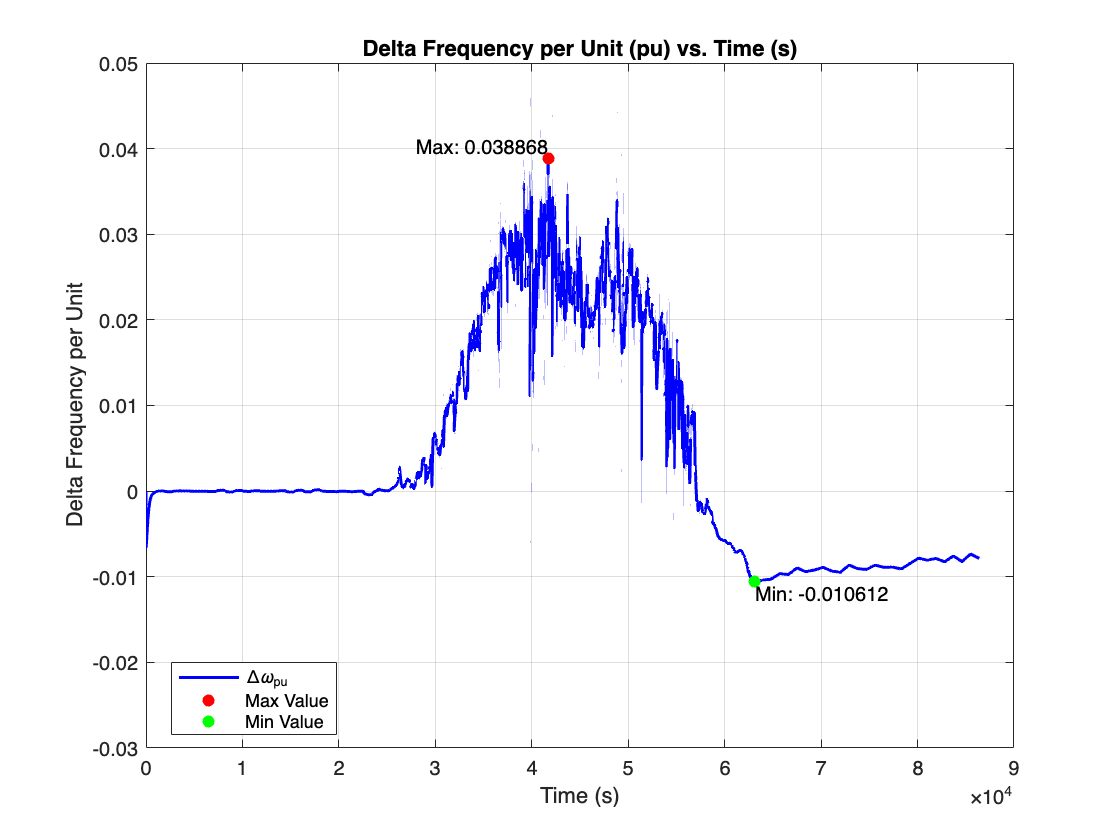

x = log.getElement("delta_wpu").Values.Time;
delta_wpu = log.getElement("delta_wpu").Values.Data;
[max_val, max_idx] = max(delta_wpu);
[min_val, min_idx] = min(delta_wpu);
figure;
plot(x, delta_wpu, '-b', 'LineWidth', 1.5); 
hold on;
scatter(x(max_idx), max_val, 'ro', 'filled', 'DisplayName', 'Maximum');
scatter(x(min_idx), min_val, 'go', 'filled', 'DisplayName', 'Minimum');
text(x(max_idx), max_val, sprintf('Max: %f', max_val), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
text(x(min_idx), min_val, sprintf('Min: %f', min_val), 'VerticalAlignment', 'top', 'HorizontalAlignment', 'left');
ylabel("Delta Frequency per Unit");
ylim([-0.03 0.05]);
xlabel("Time (s)");
title('Delta Frequency per Unit (pu) vs. Time (s)');
legend({'\Delta\omega_{pu}', 'Max Value', 'Min Value'}, 'Location', 'best');
grid on;
hold off;

### - Contigency Condition

## References

- Reference for IECC Lighting Power Density: [https://www.archtoolbox.com/recommended-lighting-levels](https://www.archtoolbox.com/recommended-lighting-levels)

- 2019 Solar Prices for Kenya: [https://energypedia.info/wiki/File:Solar_Prices_KE_Matrix.xlsx](https://energypedia.info/wiki/File:Solar_Prices_KE_Matrix.xlsx)

- Solar Powered Water Guidlines Rwanda: [https://drive.google.com/file/d/1lrx7iS9qK3hgrIIGmuUqderht0T_6Wgs/view?usp=sharing](https://drive.google.com/file/d/1lrx7iS9qK3hgrIIGmuUqderht0T_6Wgs/view?usp=sharing)

- National Renewable Energy Laboratory* - *Solar Installed System Cost Analysis: [https://www.nrel.gov/solar/market-research-analysis/solar-installed-system-cost.html](https://www.nrel.gov/solar/market-research-analysis/solar-installed-system-cost.html)

- Wabukala, Benard M., et al. "Assessing wind energy development in Uganda: Opportunities and challenges." *Wind Engineering* 45.6 (2021): 1714-1732. [https://journals.sagepub.com/doi/full/10.1177/0309524X20985768](https://journals.sagepub.com/doi/full/10.1177/0309524X20985768)

- Global Petrol Prices Website in Uganda: [https://www.globalpetrolprices.com/Uganda/diesel_prices/](https://www.globalpetrolprices.com/Uganda/diesel_prices/)